## **基本元器件**

**1.常相角原件Q**

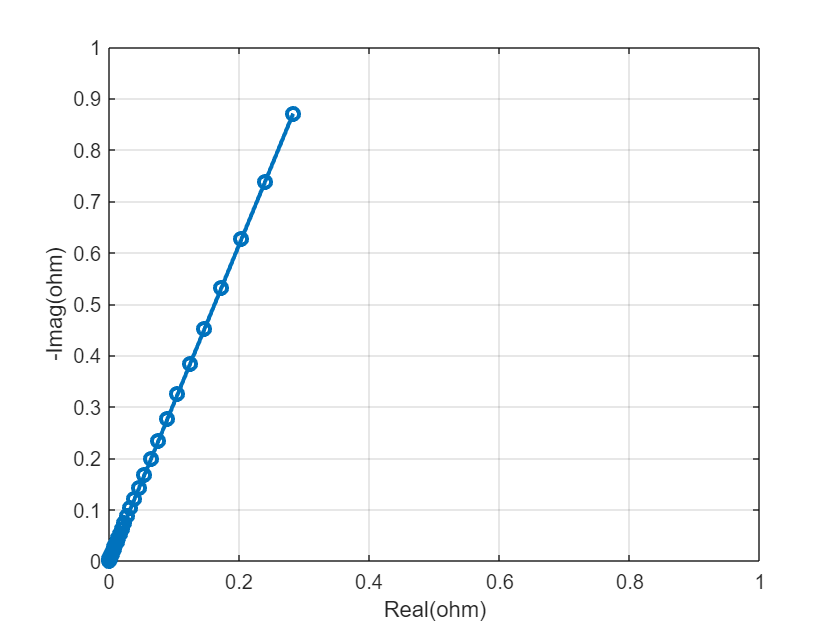

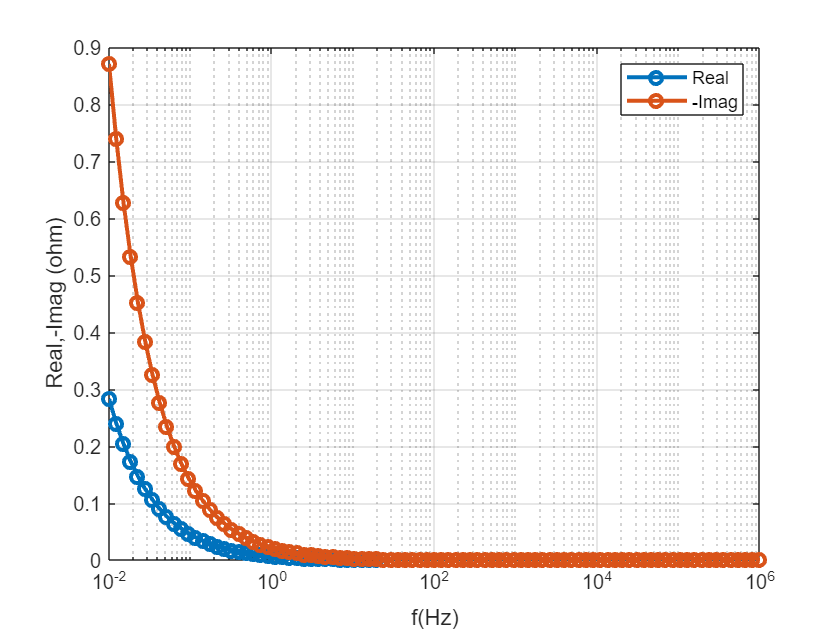

f=logspace(-2,6,91);
w=2*pi*f;
Z_Q_example=Q(2*pi*f,"n",0.8,"Q",10);
plot_EIS(w,Z_Q_example,"Nyquist",'on',"Bode",'on',"xlim_switch",'on')

**2.理想电容C**

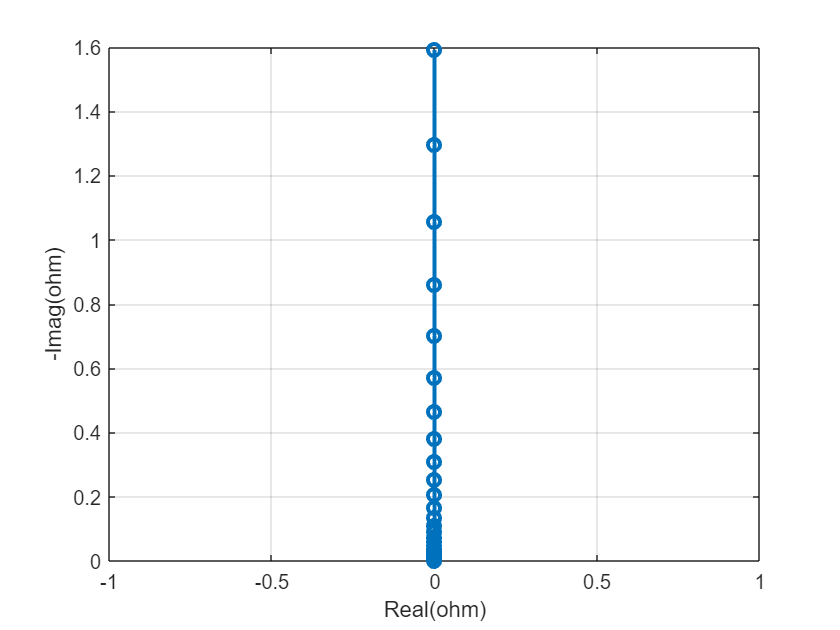

f=logspace(-2,6,91);
w=2*pi*f;
Z_C_example=C(w,"C",10);
plot_EIS(w,Z_C_example)

**3.纯电阻R**

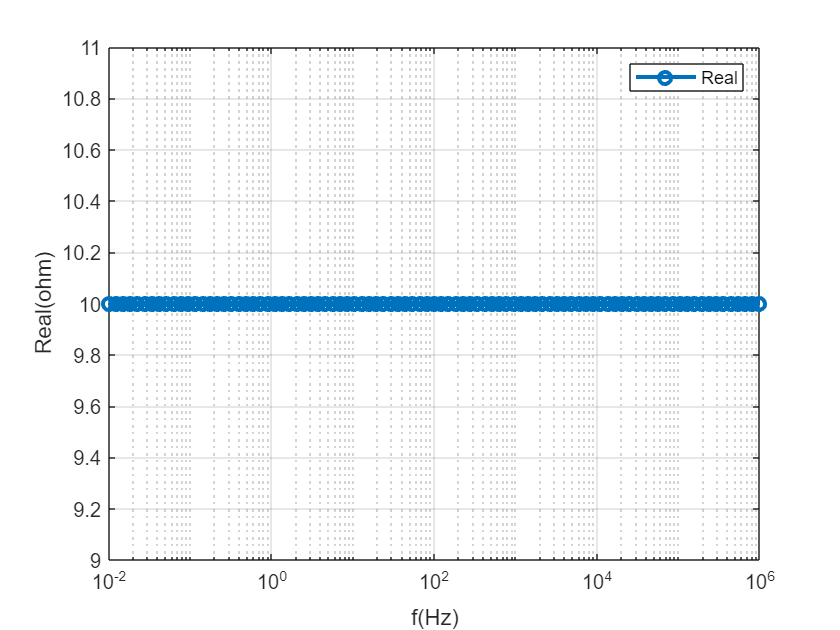

f=logspace(-2,6,91);
w=2*pi*f;
Z_R_example=R(w,"R",10);
plot_EIS(w,Z_R_example,"Nyquist","off","Bode","real")

**4.纯电感L**

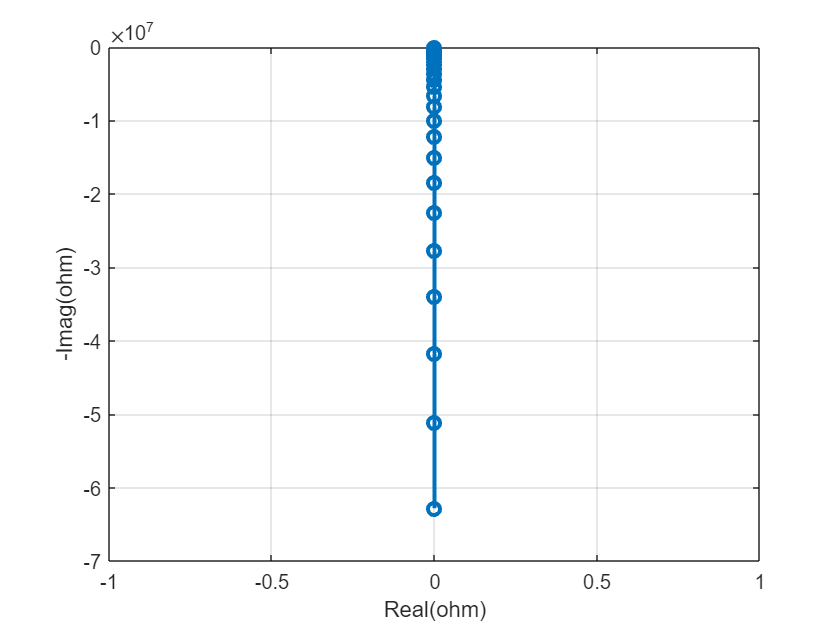

f=logspace(-2,6,91);
w=2*pi*f;
Z_L_example=L(w,"L",10);
plot_EIS(w,Z_L_example,"Nyquist","on")

**5.RQ环路**

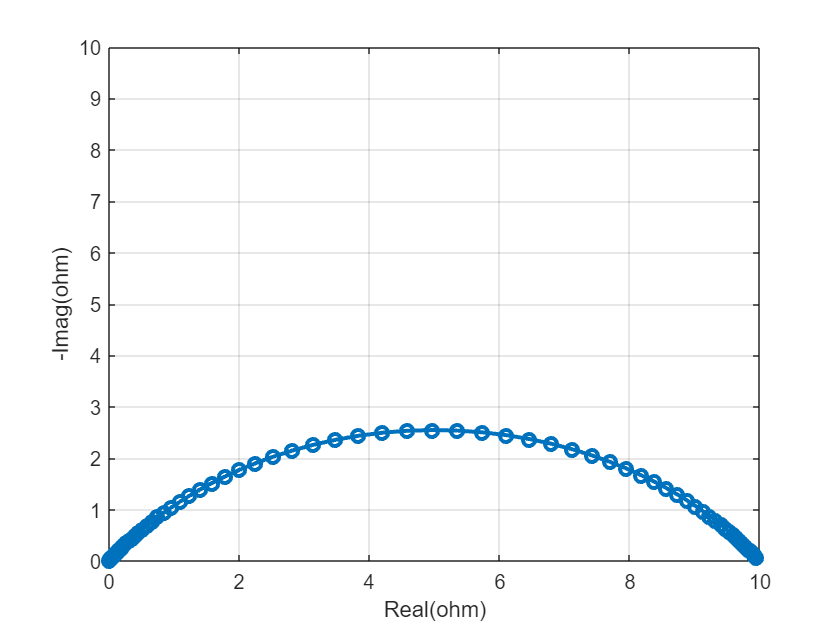

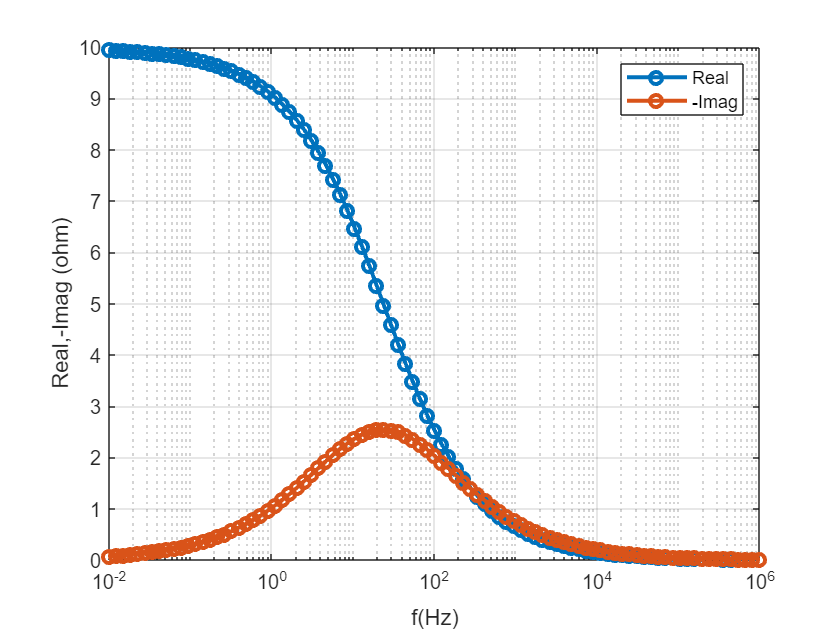

f=logspace(-2,6,91);
w=2*pi*f;
Z_RQ_example=RQ(2*pi*f,'R', 10, 'Q', 5e-3,'n',0.6);
plot_EIS(w,Z_RQ_example,"Nyquist","on","Bode","on","xlim_switch",'on')

**6.传输线模型TLM(含Rct)**

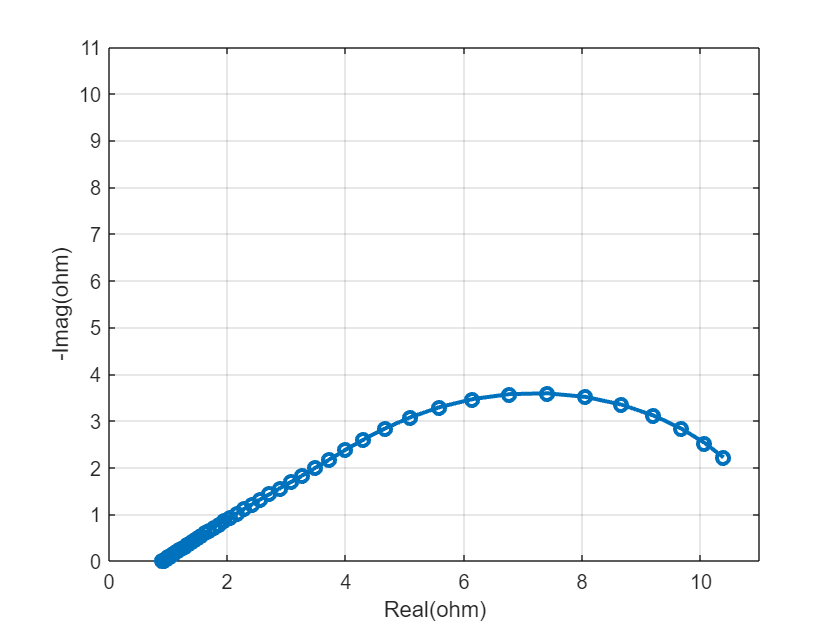

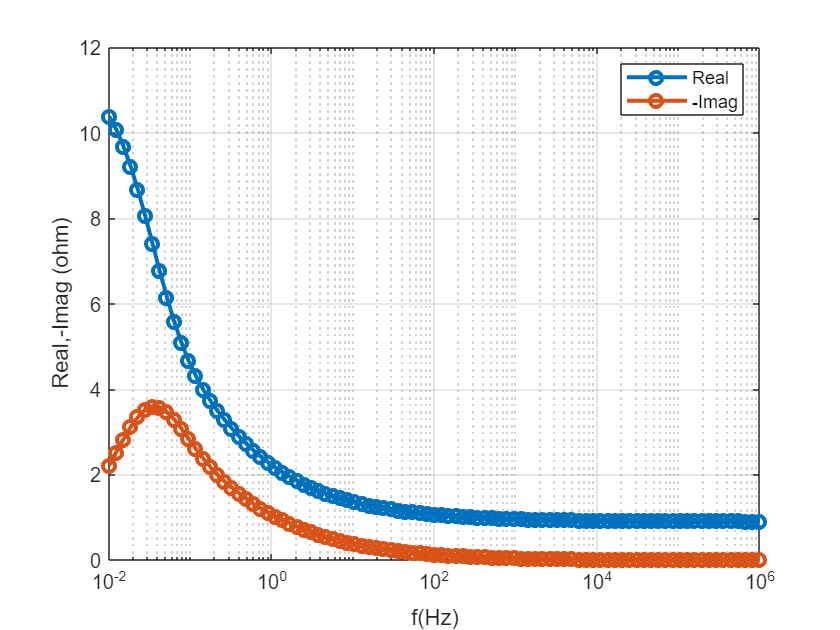

f=logspace(-2,6,91);
w=2*pi*f;
Z_interface=@(w,Rct,Qct,n_ct) RQ(w,"R",Rct,"Q",Qct,"n",n_ct);%界面阻抗表达式，采用RQ回路表示法拉第过程
Z_tlm=@(w,L,Re,Ri,Rct,Qct,n_ct) TLM(w,"L",L,"Re",Re,"Ri",Ri,"Zt",Z_interface(w,Rct,Qct,n_ct));
Z_tlm_example=Z_tlm(w,0.1,10,100,0.8,5,0.9);
plot_EIS(w,Z_tlm_example,"Bode","on","xlim_switch",'on')

**7.传输线模型TLM(不含Rct)**

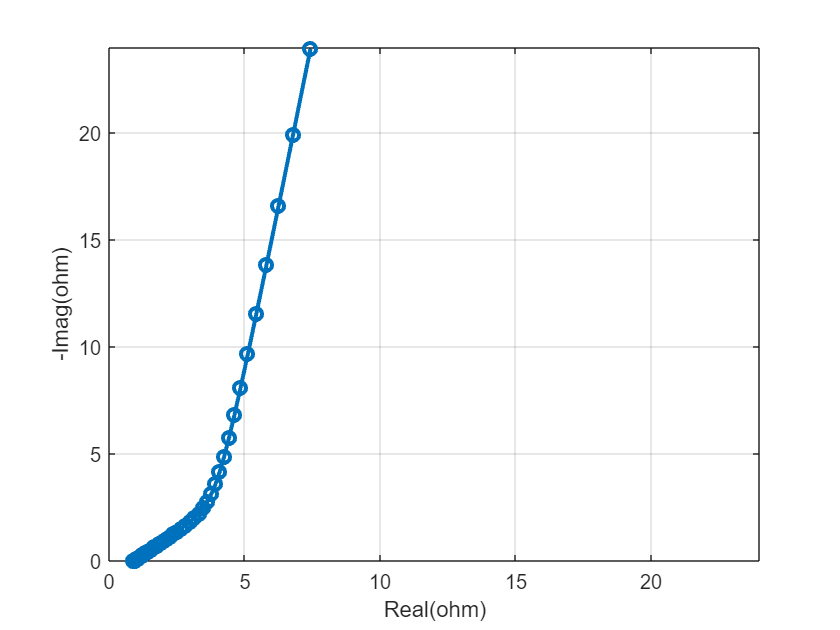

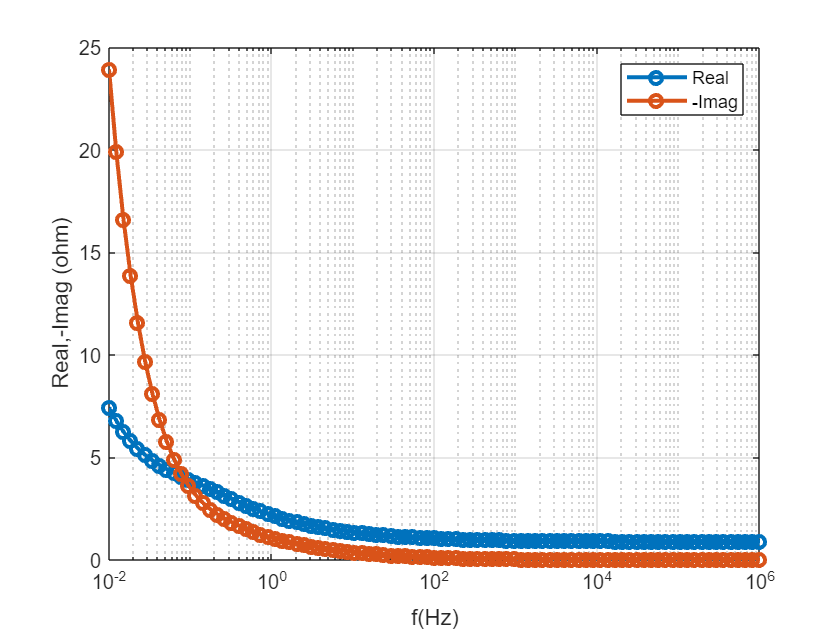

f=logspace(-2,6,91);
w=2*pi*f;
Z_interface2=@(w,Q_interf,n_interf) Q(w,"Q",Q_interf,"n",n_interf);%界面阻抗表达式，采用Q回路表示非法拉第过程,n=1表示纯电容
Z_tlm=@(w,L,Re,Ri,Q_interf,n_interf) TLM(w,"L",L,"Re",Re,"Ri",Ri,"Zt",Z_interface2(w,Q_interf,n_interf));
Z_tlm_example=Z_tlm(w,0.1,10,100,5,0.9);
plot_EIS(w,Z_tlm_example,"Bode","on","xlim_switch",'on')

**8.简化传输线模型TLMs(忽略电子电阻，不含Rct)**

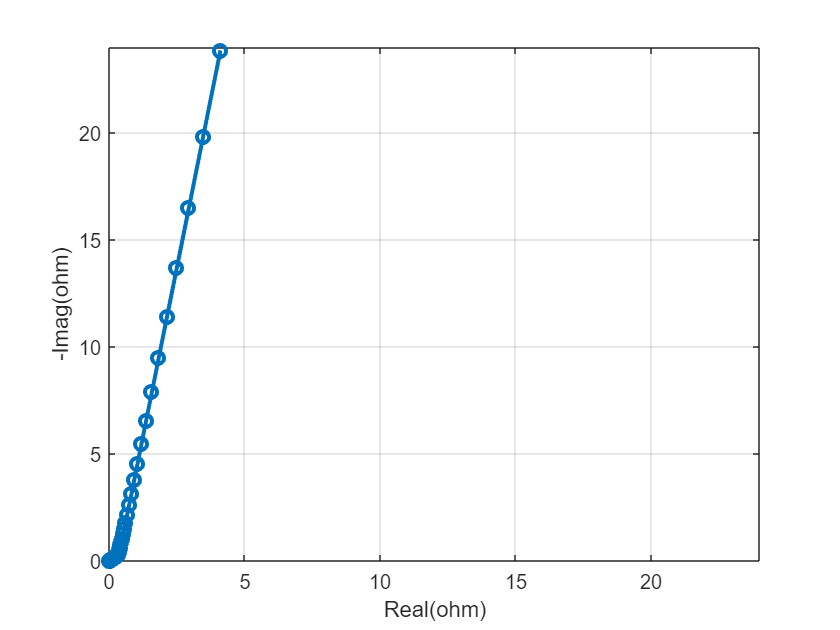

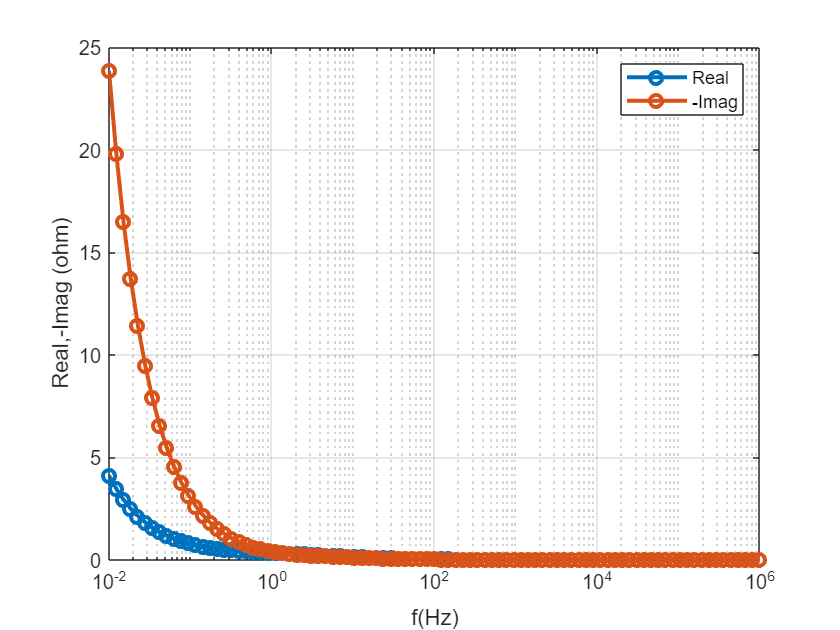

f=logspace(-2,6,91);
w=2*pi*f;
Z_interface2=@(w,Q_interf,n_interf) Q(w,"Q",Q_interf,"n",n_interf);%界面阻抗表达式，采用Q回路表示非法拉第过程,n=1表示纯电容
Z_tlm2=@(w,L,Ri,Q_interf,n_interf) TLM(w,"L",L,"Ri",Ri,"Zt",Z_interface2(w,Q_interf,n_interf));
Z_tlm2_example=Z_tlm2(w,0.1,10,5,0.9);
plot_EIS(w,Z_tlm2_example,"Bode","on","xlim_switch",'on')

**9.半无限扩散阻抗Zw**

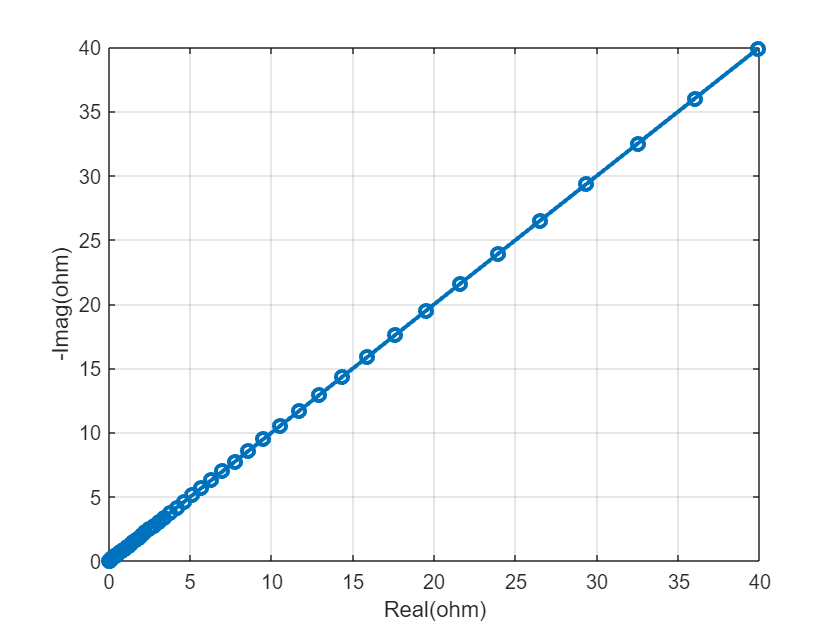

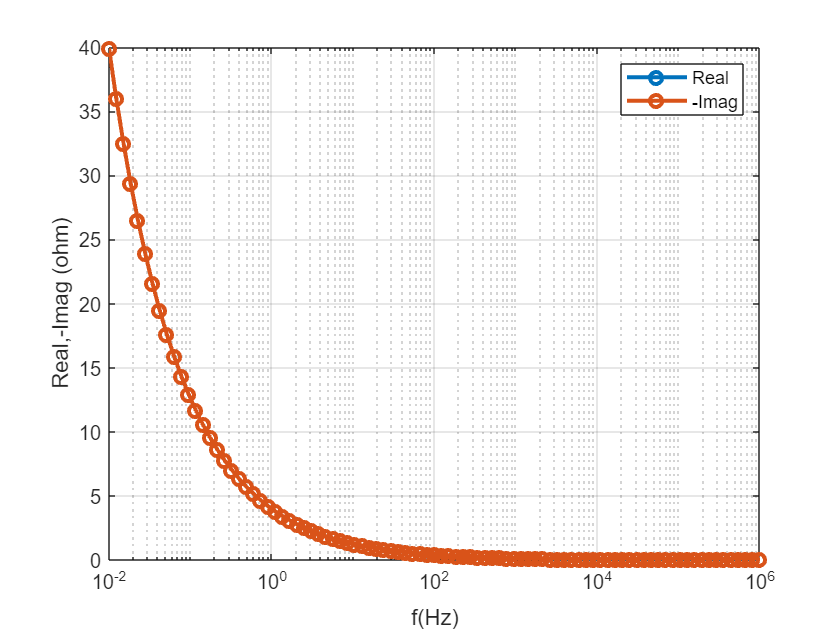

f=logspace(-2,6,91);
w=2*pi*f;
Zw_example=Zw(w,"sigma",10);
plot_EIS(w,Zw_example,"Bode","on")

**10.有限空间扩散阻抗ZT**

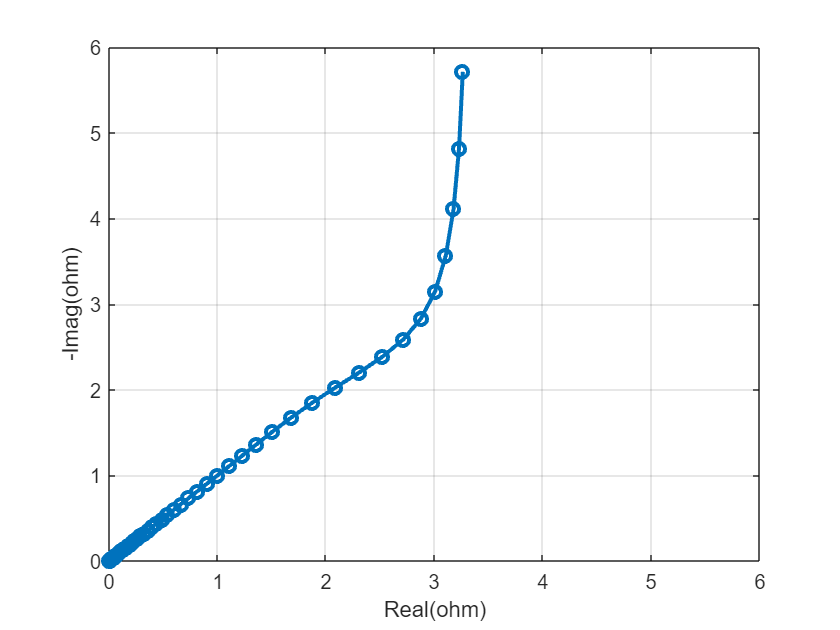

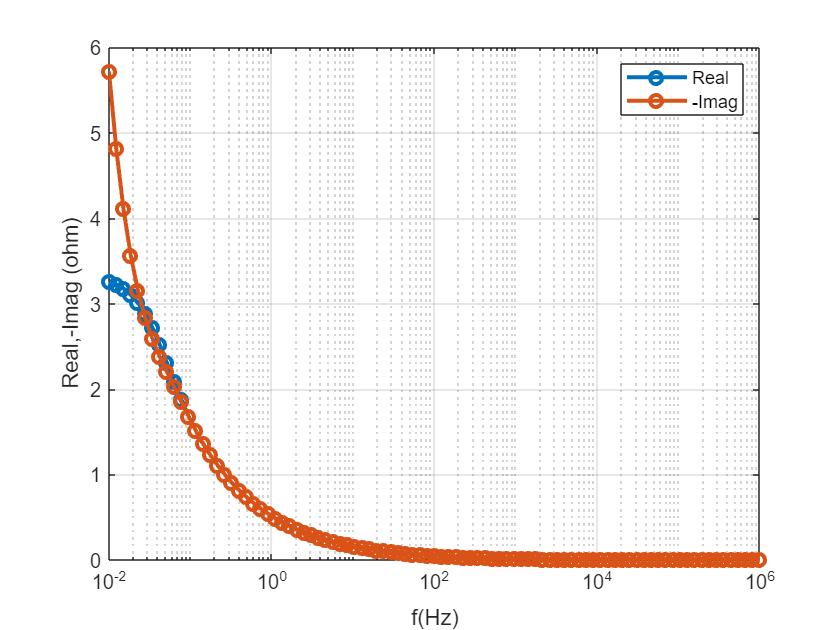

f=logspace(-2,6,91);
w=2*pi*f;
ZT_example=ZT(w,"Rw",10,"tau",30,"n_w",0.5);
plot_EIS(w,ZT_example,"Bode","on","xlim_switch",'on')

**11.有限长度扩散阻抗**

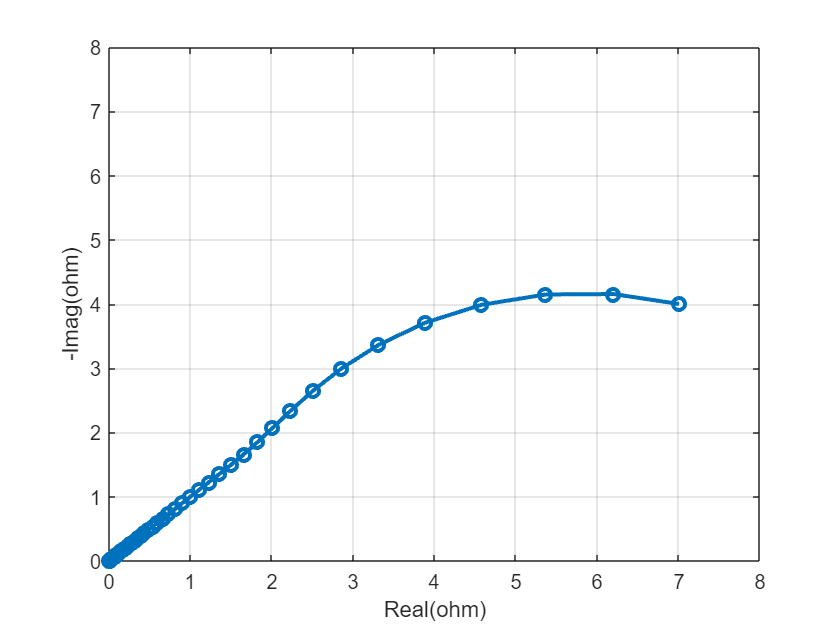

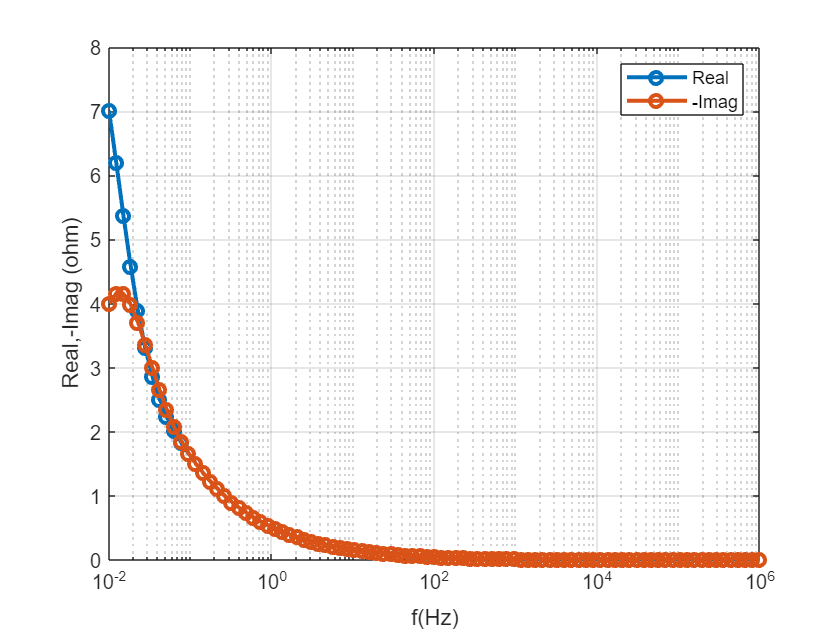

f=logspace(-2,6,91);
w=2*pi*f;
Zo_example=Zo(w,"Rw",10,"tau",30,"n_w",0.5);
plot_EIS(w,Zo_example,"Bode","on","xlim_switch",'on')

## **使用函数句柄组成复杂电路**

**1.Rs-RQ(Randles)**

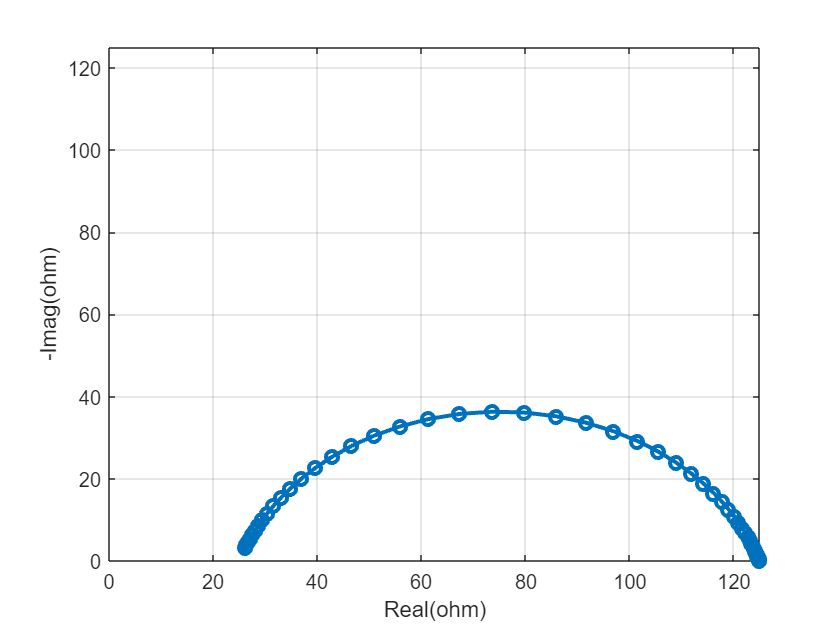

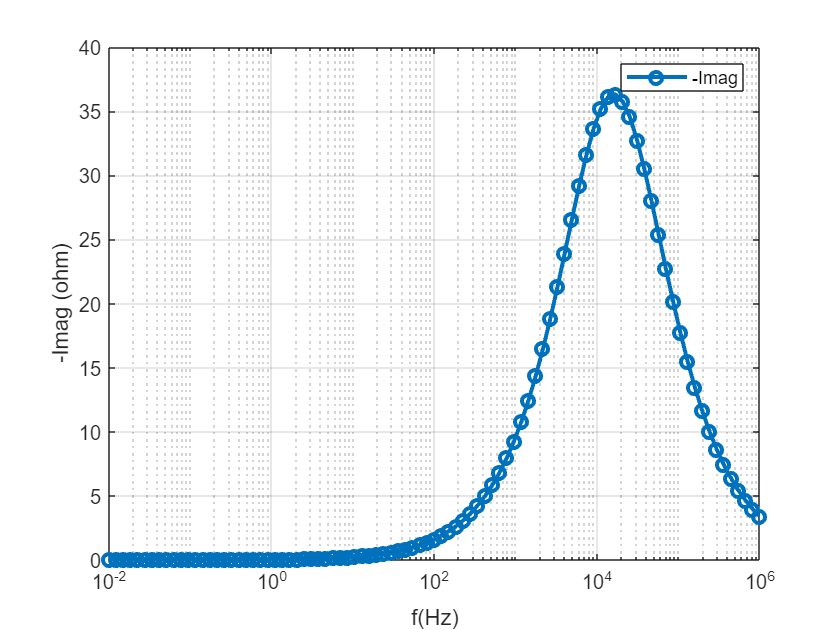

f=logspace(-2,6,91);
w=2*pi*f;
Z1=@(w,R0) R(w,'R',R0);
Z_RQ=@(w,R1,Q1,n) RQ(w,'R', R1, 'Q', Q1,'n',n);
Z_Randles=@(w,R0,R1,Q1,n) Z1(w,R0)+Z_RQ(w,R1,Q1,n);
Z_Randles_example=Z_Randles(w,25,100,10^-6,0.8);
plot_EIS(w,Z_Randles_example,"Bode","imag","xlim_switch",'on')

**2.Rs-RQ-Zw**

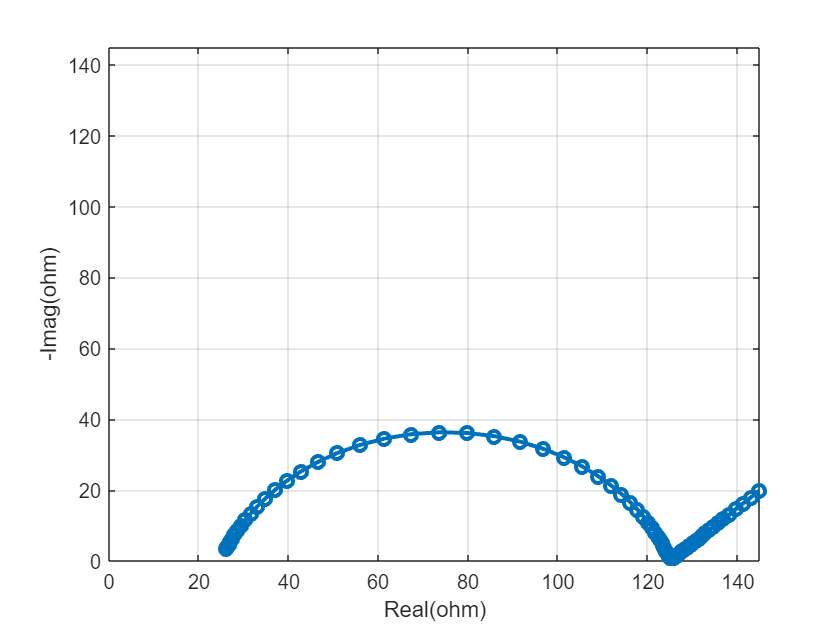

f=logspace(-2,6,91);
w=2*pi*f;
Z1=@(w,R0) R(w,'R',R0);
Z_RQ=@(w,R1,Q1,n) RQ(w,'R', R1, 'Q', Q1,'n',n);
Z_W=@(w,sigma) Zw(w,"sigma",sigma);
Z_Randles=@(w,R0,R1,Q1,n,sigma) Z1(w,R0)+Z_RQ(w,R1,Q1,n)+Z_W(w,sigma);%各部分串联，使用加和
Z_Randles_example2=Z_Randles(w,25,100,10^-6,0.8,5);
plot_EIS(w,Z_Randles_example2,"xlim_switch",'on')

**3. RL**

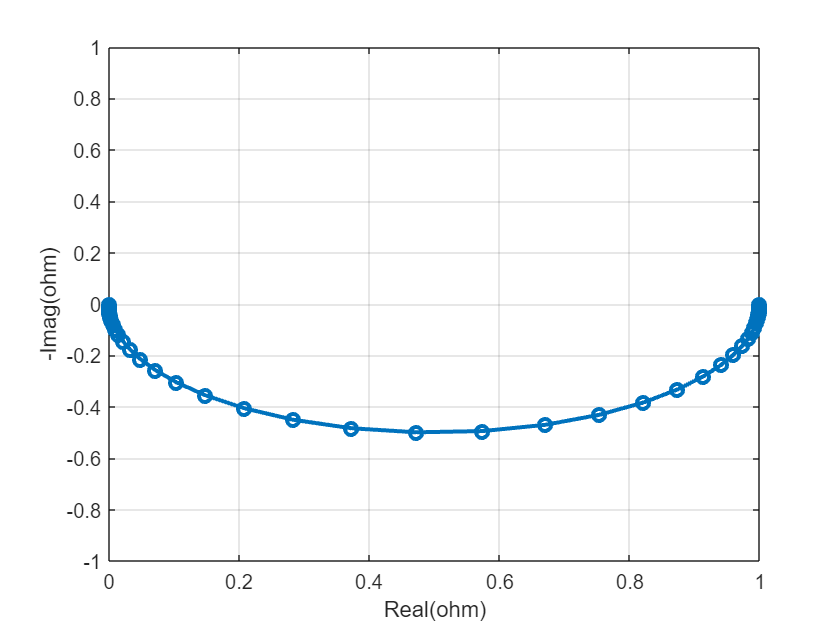

f=logspace(-2,6,91);
w=2*pi*f;
Z_R=@(w,R0) R(w,'R',R0);
Z_L=@(w,L1) L(w,"L",L1);
Z_RL=@(w,R0,L1) 1./(1./Z_R(w,R0)+1./Z_L(w,L1));%并联，使用导纳加和
plot_EIS(w,Z_RL(w,1,1e-3),"xlim_switch",'on')

## **电路参数拟合**

**案例1:-TLMs-**

**step1:使用函数句柄定义电路，以TLMs为例**

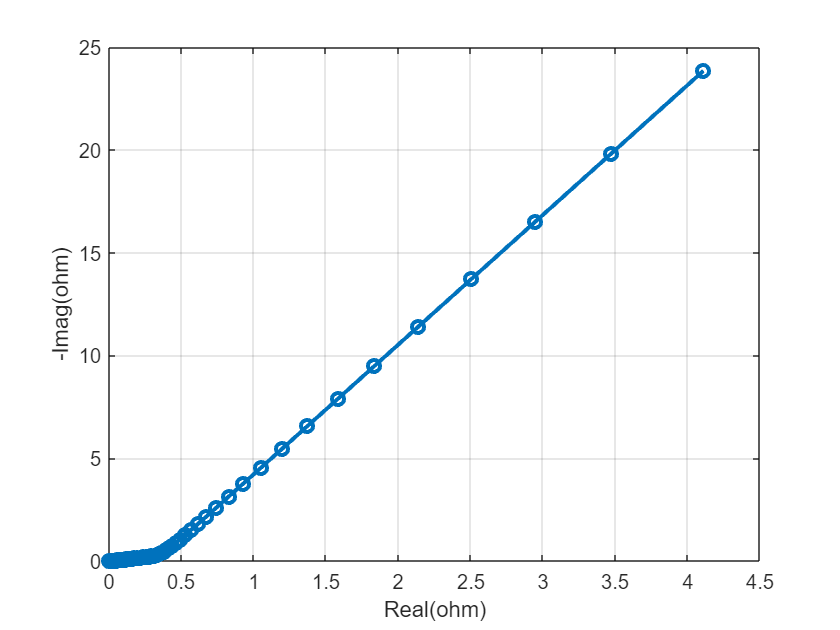

f=logspace(-2,6,91);
w=2*pi*f;

Z_interface=@(w,Q_interf,n_interf) Q(w,"Q",Q_interf,"n",n_interf);%界面阻抗表达式，采用Q回路表示非法拉第过程,n=1表示纯电容
Z_tlms=@(w,L,Ri,Q_interf,n_interf) TLM(w,"L",L,"Ri",Ri,"Zt",Z_interface(w,Q_interf,n_interf));
%定义待拟合电路，待拟合参数向量化
sim_circuit=@(param)Z_tlms(w,param(1),param(2),param(3),param(4));

%准备实验数据
Z_tlms_example=Z_tlms(w,0.1,10,5,0.9);
plot_EIS(w,Z_tlms_example,"Bode","off")

**step2:使用fit_EIS进行拟合**

help fit_EIS

 Return the circuit paramter value and erros
 Inputs
 ---------------
  w:= Angular frequency [1/s]
  exp_data:a complex matrix size:(1*length(w))
  sim_circuit:object circuit function handle
  param_0: the inital of circuit parameter,size:(1:N)
  options:is a structure with fields:
  method:slover method,the default is 'fminunc';Include:'lsqnonlin','fminunc','fmincon','pso'
  ub:the upper of circuit paramter, size:(1:N)
  lb:the lower of circuit paramter, size:(1:N)
  error_type:The type of error function to calculate,the default is 'Chi-2';Include:'Chi-2','RMSE'



%设置待辨识参数上下界
param_0=[0.1,5,2,0.75];
lb=0.1*param_0;lb(end)=0.5;lb(1)=0.99*param_0(1);
ub=10*param_0;ub(end)=1;ub(1)=1.01*param_0(1);

%pso求解,需提供上下界
[x,fav]=fit_EIS(w,Z_tlms_example,sim_circuit,[],'method','pso','lb',lb,'ub',ub)

Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x =     0.1000   10.0009    5.0005    0.9000


fav = 2.3433e-13

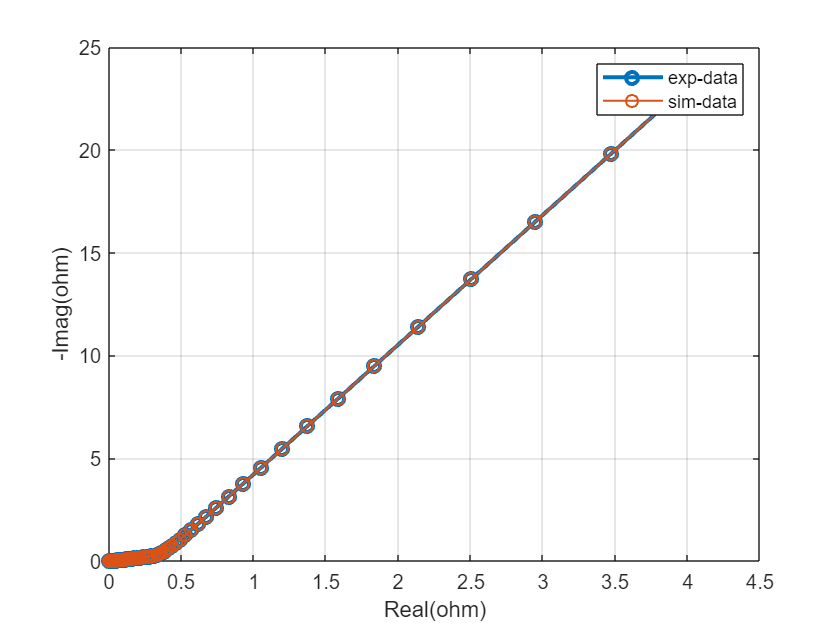

%绘制结果
% plot_EIS(w,sim_circuit(x))
% hold on
% plot(real(Z_tlms_example),-imag(Z_tlms_example),'-o','DisplayName','exp'),legend({'sim','exp'})
plot_fit_result(w,Z_tlms_example,sim_circuit,x,"Nyquist",'on','Bode','on')

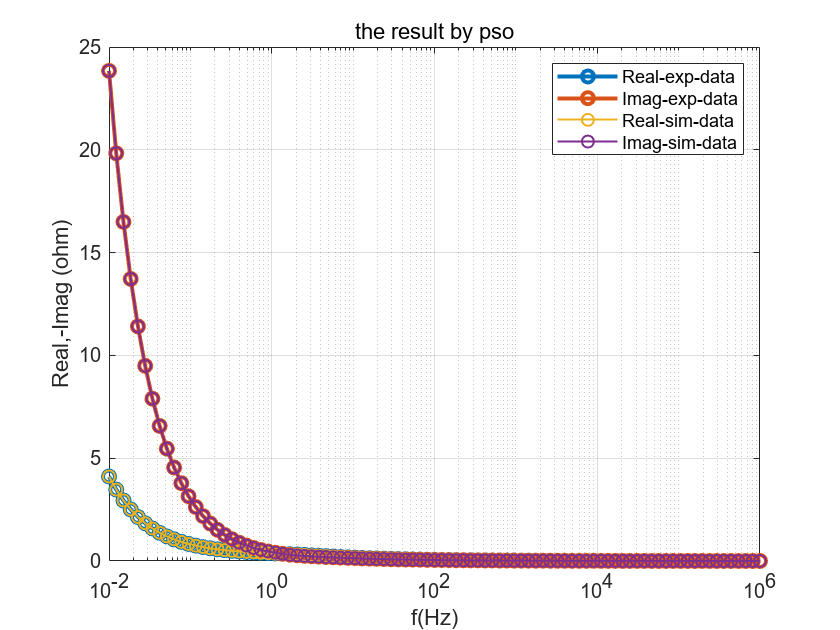

title('the result by pso')

%'fmincon'求解,需要提供猜测初始值与上下界
[x,fav]=fit_EIS(w,Z_tlms_example,sim_circuit,param_0,'method','fmincon','lb',lb,'ub',ub)


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =     0.1000   10.0008    5.0004    0.9000


fav = 1.8166e-13

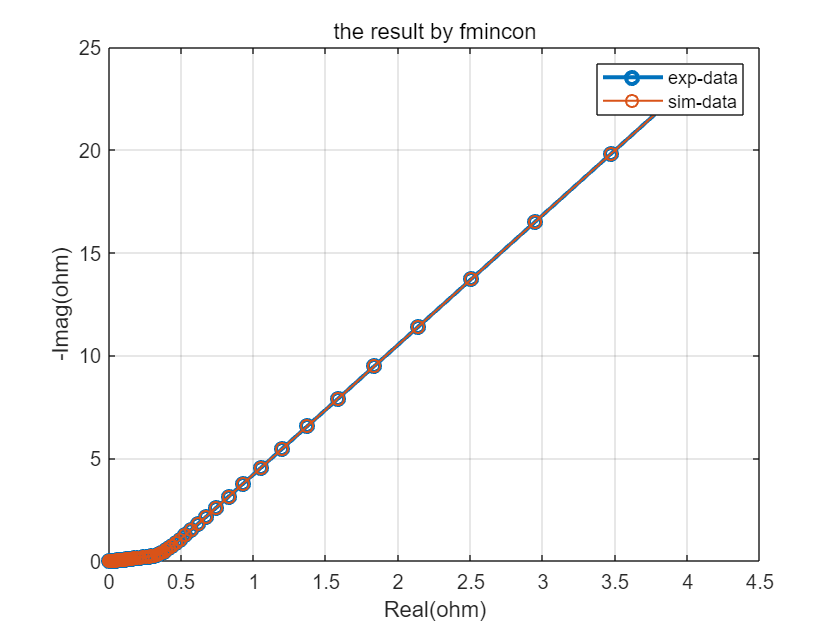

%绘制结果
plot_fit_result(w,Z_tlms_example,sim_circuit,x)
title('the result by fmincon')

%'fminucn'求解,需要提供猜测初始值
[x,fav]=fit_EIS(w,Z_tlms_example,sim_circuit,param_0,'method','fminunc')


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


x =     0.2072    4.8259    2.4130    0.9000


fav = 9.8210e-10

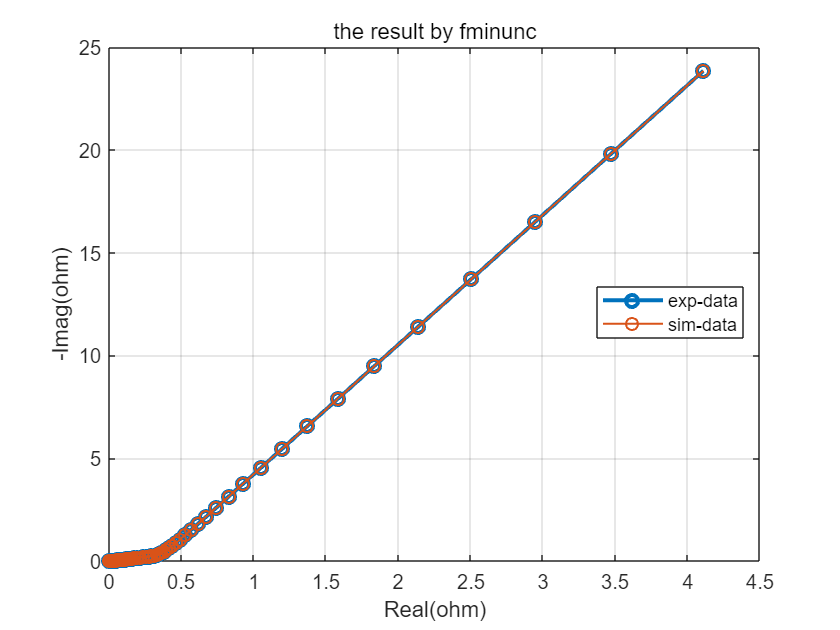

%绘制结果
plot_fit_result(w,Z_tlms_example,sim_circuit,x)
title('the result by fminunc')

%'lsqnonlin'求解,需要提供猜测初始值
[x,fav]=fit_EIS(w,Z_tlms_example,sim_circuit,param_0,'method','lsqnonlin','error_type','Chi-2')


Solver stopped prematurely.

lsqnonlin stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 4.000000e+02.



x =     0.1263    9.9279    3.9872    0.9031


fav = 4.8280e-04

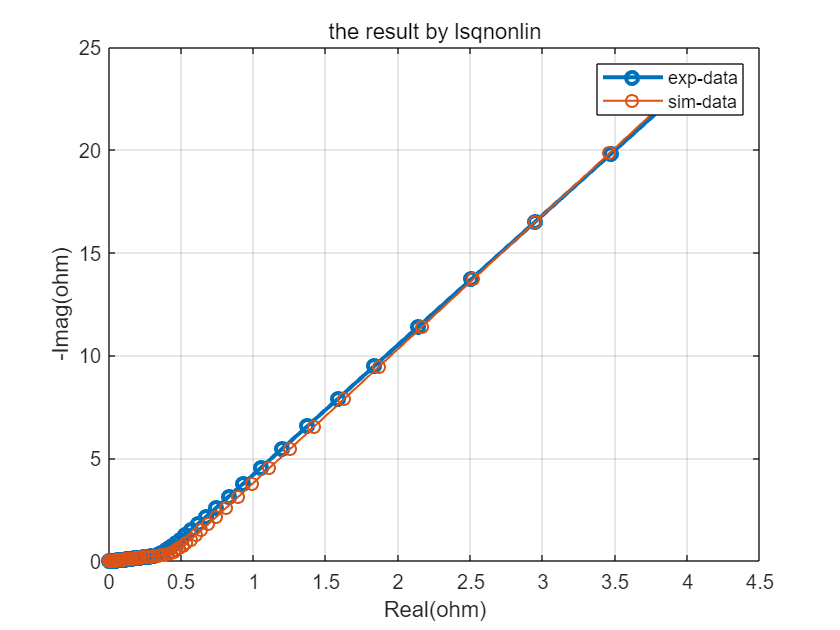

%绘制结果
plot_fit_result(w,Z_tlms_example,sim_circuit,x)
title('the result by lsqnonlin')

**案例2:-L-TLM-**

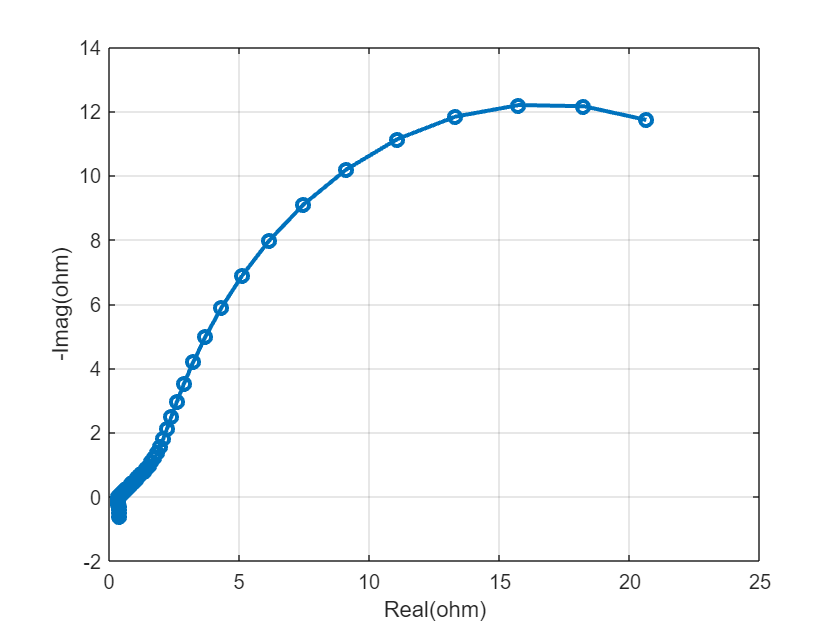

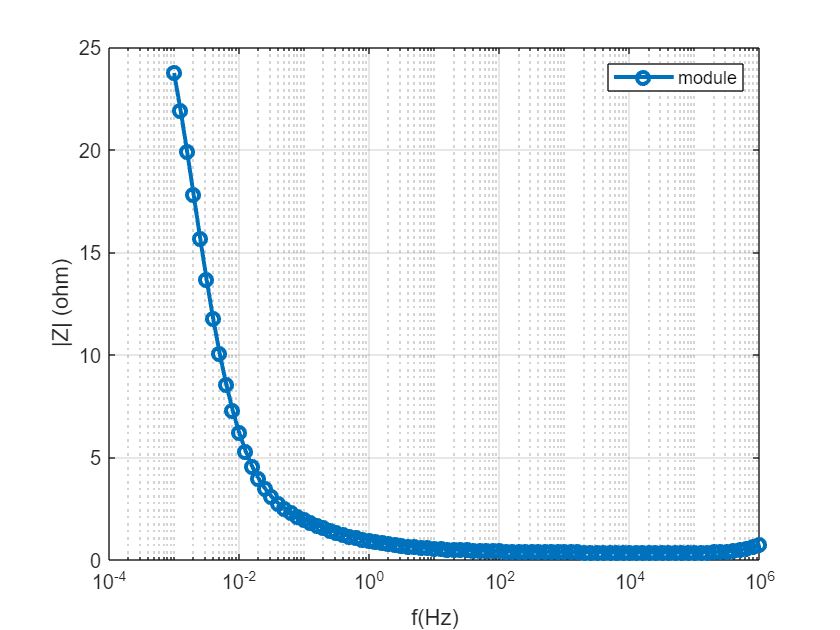

% 定义拟合电路
f=logspace(-3,6,91);
w=2*pi*f;
Z_L=@(w,L1) L(w,"L",L1);
Z_R=@(w,R1) R(w,"R",R1);
Z_interface=@(w,R_ct,Q_interf,n_interf) RQ(w,"R",R_ct,"Q",Q_interf,"n",n_interf);
Z_total=@(w,L1,R1,delta,Ri,Re,R_ct,Q_interf,n_interf) 1./(1./Z_L(w,L1)+1./Z_R(w,R1))...
    +TLM(w,"L",delta,"Ri",Ri,"Re",Re,"Zt",Z_interface(w,R_ct,Q_interf,n_interf));
sim_circuit=@(param) Z_total(w,param(1),param(2),param(3),param(4),param(5),param(6),param(7),param(8));

%准备实验数据
Z_tlm_example=Z_total(w,1e-7,8,0.1,50,4,3,20,0.87);
plot_EIS(w,Z_tlm_example,"Bode","module")


%猜测初始值，设置上下界
param_0=[0.6/(2*pi*10^6),0.5,0.1,60,0.6,5*0.1,1/(2*pi*0.01*5),0.75]

param_0 =     0.0000    0.5000    0.1000   60.0000    0.6000    0.5000    3.1831    0.7500


lb=0.01*param_0;
ub=100*param_0;
lb(3)=0.99*param_0(3);ub(3)=1.01*param_0(3);
lb(end)=0.5;ub(end)=1;
[x,fav]=fit_EIS(w,Z_tlm_example,sim_circuit,param_0,'method','fmincon','lb',lb,'ub',ub)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =     0.0000    2.3440    0.0999   64.4441    3.9394    2.7875   24.8421    0.9148


fav = 0.2015

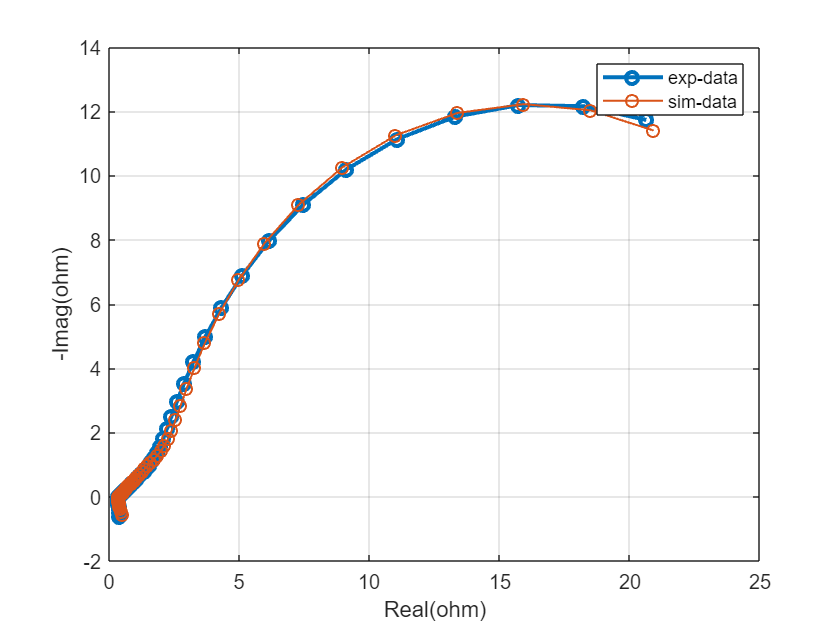

%绘制拟合结果
plot_fit_result(w,Z_tlm_example,sim_circuit,x,"Nyquist",'on','Bode','on')

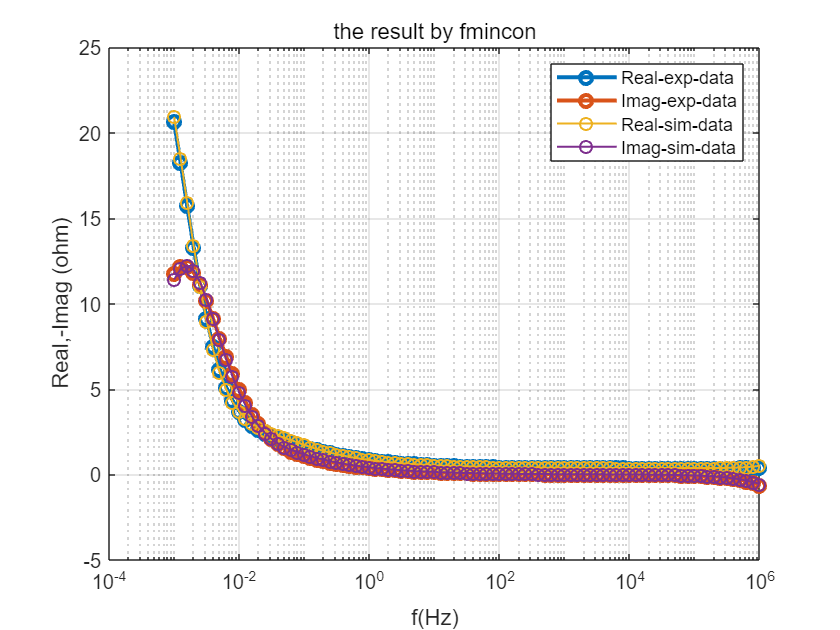

title('the result by fmincon')

**案例3：-LRs-RQ-ZT-**

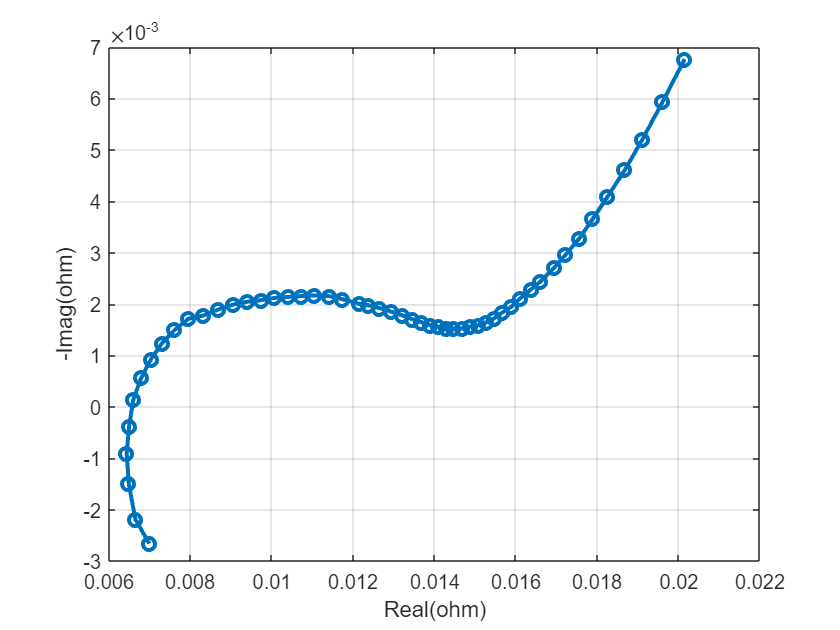

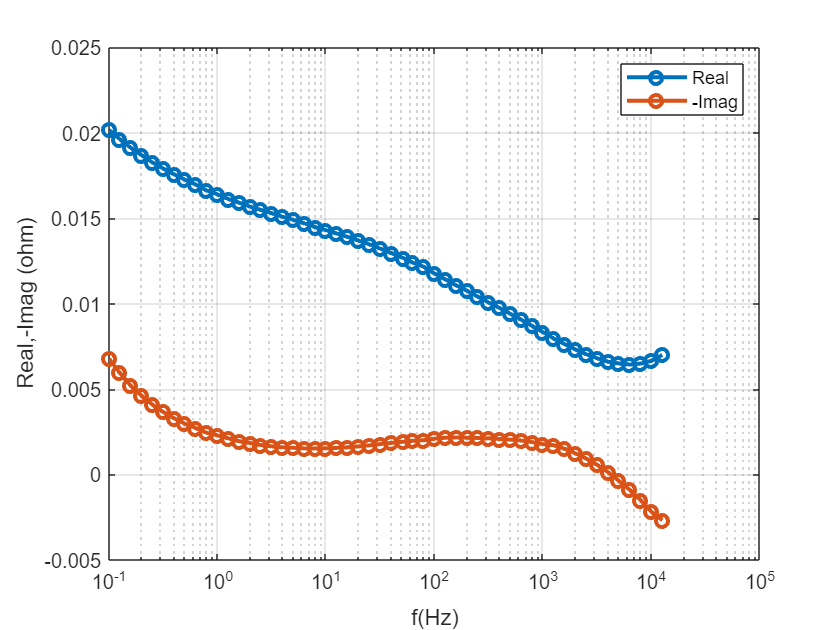

%导入实验数据并绘Nyquist & Bode图
raw_exp=readmatrix("EIS_data.xlsx");
star_index=10;
f=raw_exp(star_index:end,1);
w=2*pi*f;
exp_data=raw_exp(star_index:end,2)'+1j*(raw_exp(star_index:end,3)');
plot_EIS(w,exp_data,"Bode",'on')

%使用函数句柄定义拟合电路
Z_R=@(w,R0) R(w,'R',R0);
Z_L=@(w,L1) L(w,"L",L1);
Z_RQ=@(w,R1,fs,n) RQ(w,'R', R1, 'fs', fs,'n',n);
Z_T=@(w,Rw,tau_w,n_w) ZT(w,"Rw",Rw,"tau",tau_w,"n_w",n_w);
Z_Randles=@(w,R0,L1,R1,fs,n,Rw,tau_w,n_w) 1./(1./Z_L(w,L1)+1./Z_R(w,R1))+Z_RQ(w,R1,fs,n)+Z_T(w,Rw,tau_w,n_w);
sim_circuit=@(param) Z_Randles(w,param(1),param(2),param(3),param(4),param(5),param(6),param(7),param(8));

%设置待拟合参数的上下界
param_0=[6e-5,0.0026/(2*pi*12590),0.008,300,0.8,0.005,100,0.8];
lb=0.01*param_0;
ub=10*param_0;
lb(4)=100;ub(4)=2000;
lb(5)=0.1;ub(5)=1;
lb(end)=0.1;ub(end)=0.5;

%求解与绘制结果
[x,fav]=fit_EIS(w,exp_data,sim_circuit,param_0,'method','pso','lb',lb,'ub',ub)

Optimization ended: relative change in the objective value 
over the last OPTIONS.MaxStallIterations iterations is less than OPTIONS.FunctionTolerance.


x = 1.0e+03 *

    0.0000    0.0000    0.0000    1.6421    0.0004    0.0000    0.0478    0.0005


fav = 3.1061e-04

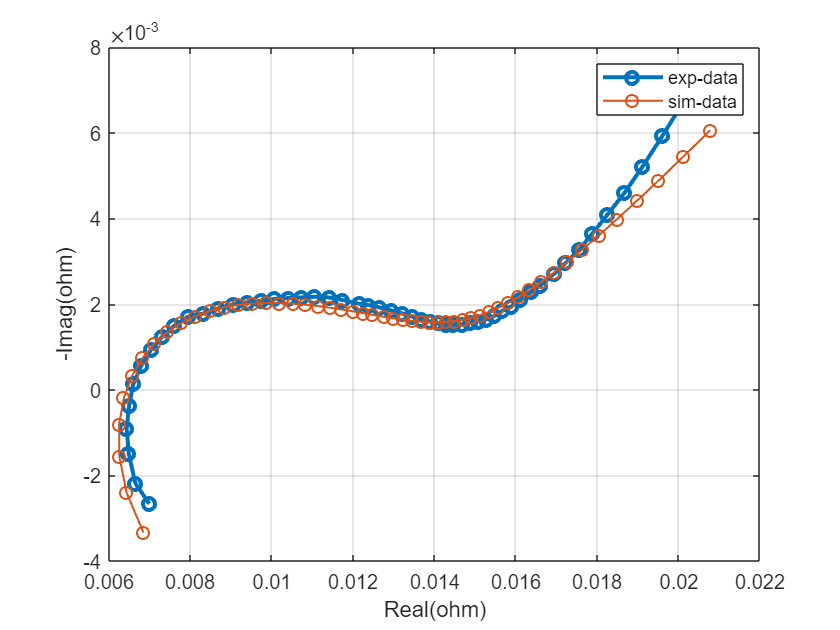

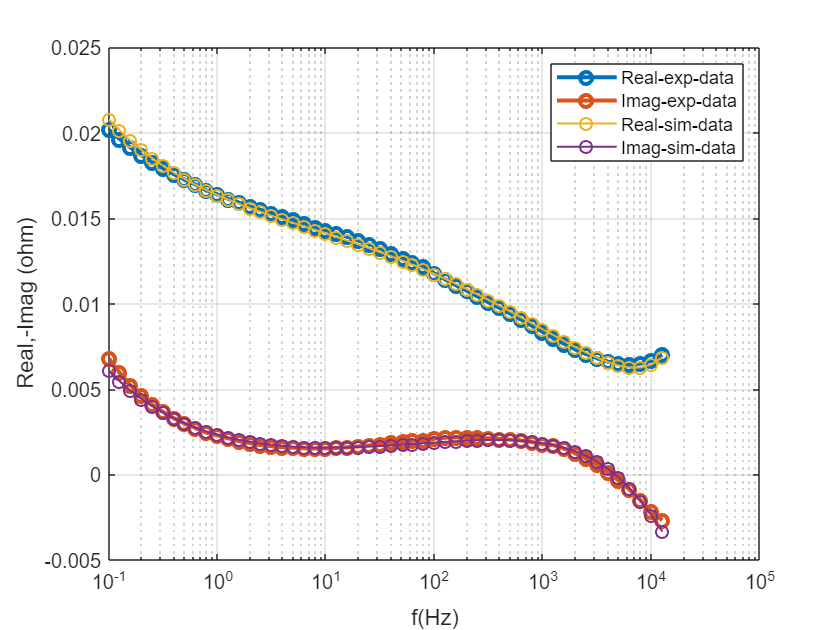

plot_fit_result(w,exp_data,sim_circuit,x,"xlim_switch",'off','Bode','on')